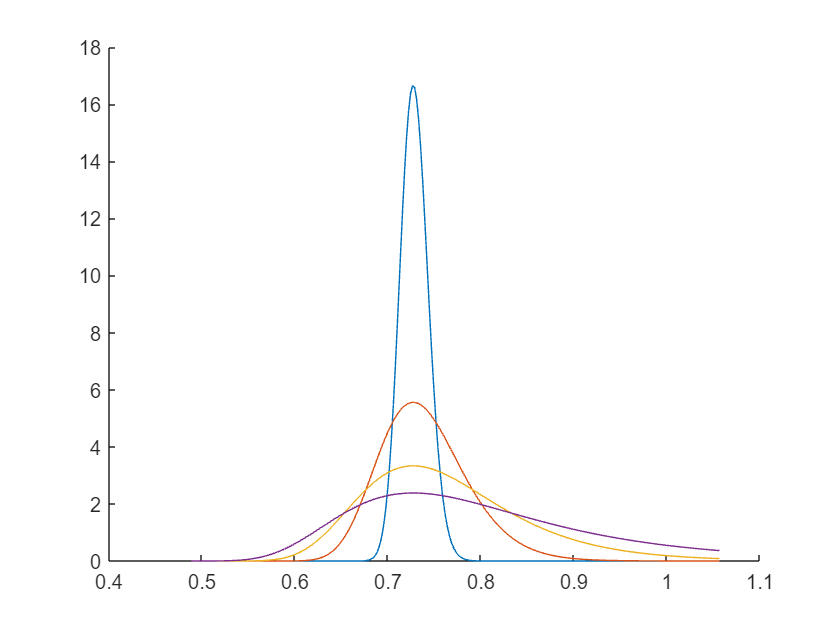

clc;
clear all;
close all;
A=3;
n=sqrt(A);
L_0=9*10^-9;
L=linspace(2*10^-9, 15*10^-9, 500);
E_g_InAs=0.354;
E_g_GaAs = 1.424;
m_0 = 9.1093837*10^(-31);
me_eff_GaAs= 0.067;
mh_eff_GaAs= 0.45;
me_eff_InAs=0.041;
mh_eff_InAs=0.417;
m_0 = 9.1093837*10^(-31);
hbar = 1.0545718*10^(-34);
mu_InAs = 1/(1/(m_0*me_eff_InAs)+1/(m_0*mh_eff_InAs));
q=1.60217663*10^-19;
photon_energy=linspace (0.4, 2.4, 500);
x= photon_energy-E_g_InAs;
chi = sqrt((2*mu_InAs*L_0^2*x*q)/(pi^2*hbar^2));

xeta=0.02;

relative_absorption = (1/ (xeta * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta^2));

xeta_2=0.06;

relative_absorption_2 = (1/ (xeta_2 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_2^2));

xeta_3=0.1;

relative_absorption_3 = (1/ (xeta_3 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_3^2));

xeta_4=0.14;

relative_absorption_4 = (1/ (xeta_4 * n.^2)) .* exp((-(n ./ chi - 1).^2) ./ (2 * xeta_4^2));

Ve=(E_g_GaAs-E_g_InAs)*(0.6);
Vh=(E_g_GaAs-E_g_InAs)*(0.4);
E_e=(pi.^2.*hbar.^2.*A)./(2.*me_eff_InAs.*m_0.*q.*L.^2);
E_h=(pi.^2.*hbar.^2.*A)./(2.*mh_eff_InAs.*m_0.*q.*L.^2);
for i=1: length (E_e)
    if E_e(i)<=Ve
        E_e(i)=E_e(i);
    end
    if E_e(i)>=Ve
    E_e(i)=NaN;
    end
    end
E_e;
for j=1: length (E_h)
    if  E_h(j)<=Vh
        E_h(j)=E_h(j);
    end
    if E_h(j)>=Vh
    E_h(j)=NaN;
    end
    end
E_h;

photon_energy2=E_g_InAs+E_e+E_h;
x2= photon_energy2-E_g_InAs;

chi3= sqrt((2 .* mu_InAs .* L_0.^2 .* x2.* q) ./ (pi.^2 .* hbar.^2));





relative_absorption_5 = (1/ (xeta * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta^2));



relative_absorption_6 = (1/ (xeta_2 * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta_2^2));



relative_absorption_7 = (1/ (xeta_3 * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta_3^2));



relative_absorption_8 = (1/ (xeta_4 * n.^2)) .* exp((-(n ./ chi3 - 1).^2) ./ (2 * xeta_4^2));



%plot(photon_energy,relative_absorption,'--')
hold on
%plot(photon_energy,relative_absorption_2,'--')
%plot(photon_energy,relative_absorption_3,'--')
%plot(photon_energy,relative_absorption_4,'--')
plot(photon_energy2,relative_absorption_5)
plot(photon_energy2,relative_absorption_6)
plot(photon_energy2,relative_absorption_7)
plot(photon_energy2,relative_absorption_8)
hold off